# Prelab

%Type this follwing code to your lab report!!!!!!!!!!!
%Bonus : if you can make proper comments for the blank
% '%' and questions shows below, 
% you will get bonus (max:5'').
H = tf(5,[1 5])


H =
 
    5
  -----
  s + 5
 
Continuous-time transfer function.



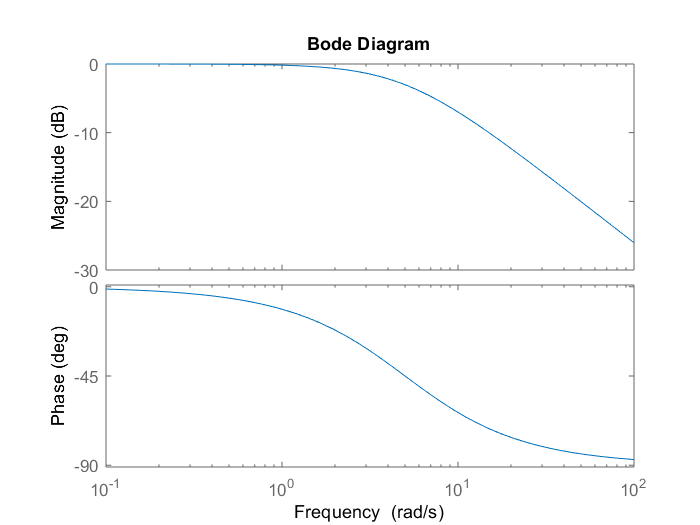

bode(H)

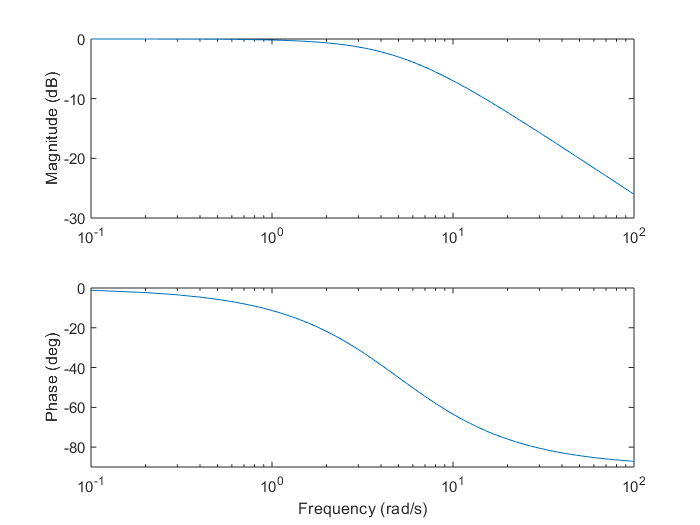

%For proving (c)
w = 0.1:0.1:100;
%
M = 5./sqrt(25+w.^2);
%
Phi = 180*atan(-0.2*w)/pi;
figure
subplot(211)
% why should we use semilogx and log10 not log?
semilogx(w,20*log10(M));
ylabel('Magnitude (dB)')
xlim([0.1,100])
ylim([-30,0])
subplot(212)
semilogx(w,Phi);
ylim([-90,0])
ylabel('Phase (deg)')
xlabel('Frequency (rad/s)')

# 4.1

1

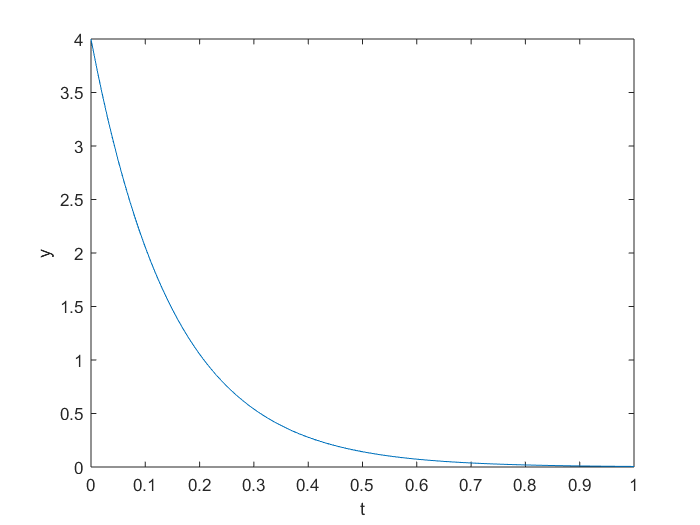

load('EE105_Lab3data.mat')
figure
plot(t,y)
xlabel('t');ylabel('y');

2

Time constant

%First method
y_tau = 0.37*y(1);
index = find(abs(y_tau-y)==min(abs(y_tau-y)),1);
tau_1 = t(index)

tau =    0.150000000000000



%Second method
%Compute dy/dt
dydt = (y(2:101)-y(1:100))./(t(2:101)-t(1:100));

dydt =  -25.797205987352889 -24.133466395468115 -22.577026385986269 -21.120965885333248 -19.758811116343807 -18.484505815259944 -17.292384305033288 -16.177146305209707 -15.133833366402135 -14.157806824573781 -13.244727177117072 -12.390534789031122 -11.591431843415856 -10.843865456033477 -10.144511878862359  -9.490261722411955  -8.878206131094617  -8.305623850189530  -7.769969126897506  -7.268860391692627  -6.800069669648103  -6.361512674657471  -5.951239542509208  -5.567426161613763  -5.208366062837417  -4.872462832386034  -4.558223014004088  -4.264249468932687  -3.989235164103907  -3.731957360952939  -3.491272179011659  -3.266109510111933  -3.055468260587932  -2.858411900322419  -2.674064298849102  -2.501605829997029  -2.340269727758035  -2.189338677175688  -2.048141625097725  -1.916050796612943  -1.792478903906801  -1.676876535126622  -1.568729711646581  -1.467557602872012  -1.372910388423014  -1.284367258192211  -1.201534541384721  -1.124043956222167  -1.051550972528402  -0.98373327

a = dydt./y(1:100);
%You may check a, all the same numbers
tau_2 = 1/(-a(1))